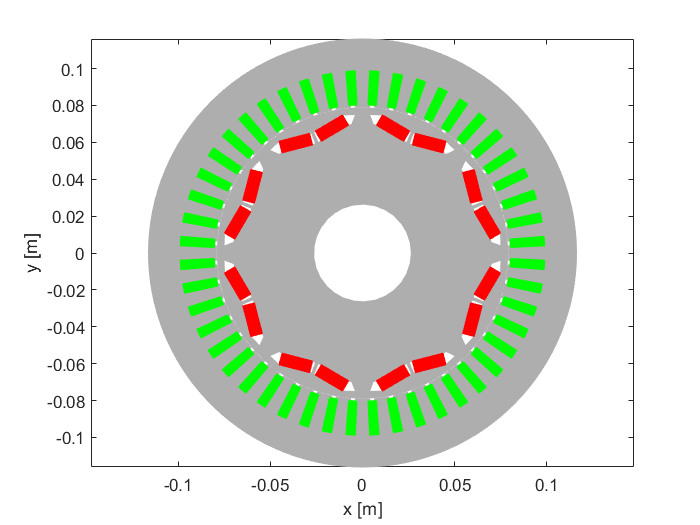

clear;
% loading data
% -----------------------------------------------------------------------
% If the data in DataPreCalculation/motor.mat changed, you have to rerun
% DataPreCalculation/CreateData.m !!!!
% -----------------------------------------------------------------------
addpath(genpath('DataPreCalculation'));
addpath(genpath('Material'));
addpath(genpath('Plotting'));
addpath(genpath('Assemble'));
addpath(genpath('Linesearch'));
load -mat motor.mat
load -mat J3_vec.mat
load -mat M_vec.mat
load -mat material.mat
load -mat e_stator_outer.mat

%sparse doesnt work with int64 elements (?)
e = e_stator_outer;
e = double(e);
t = double(t);

%plot mesh
figure
h = plotMesh(p,t,e,material);
set(h, 'LineStyle', 'none');



%size of datastructures
np=size(p,2); nt=size(t,2); ne = size(e,2);             
tic
%Caculate constant Matrices for iteration
B = calcB(p,t,e);
R_mat = Assemble_Robin_Matrix(p,e,B);                    %calculate Robin Matrix

[J_j,J_m] = Assemble_J_Vec(p,t,J3_vec,M_vec,B);
% J_j = J_j*0;
J_vec = J_j - material.nu0*J_m;
uh = zeros(np,1);                                      %initialize solution
gamma = 10^5;
num_iteration = 500; %max number of iterations
eps = 10^-6;
alpha = 1;
vh = randn(np,1);
for iter = 1:1:num_iteration
    %solve solve (N(n) + R)wh = J - F1(n) - F2(n)
    [F1_vec,F2_vec] = Assemble_F_Vec(p,t,e,uh,B,M_vec,material);  
    N_mat = Assemble_Newton_Matrix(p,t,uh,B,material);
    F = J_vec - gamma*F1_vec - F2_vec;
    A = N_mat + gamma*R_mat;
    wh = A\F;
    
    alpha = alpha*2;
    phi = @(alpha) Functional(t,uh + alpha*wh,gamma,J_j,J_m,F1_vec,material,B);
    phi_der0 = Functional_der0(wh,gamma,J_j,J_m,F1_vec,F2_vec,material);
        
    [alpha,iter_linesearch,energy] = ArmijoLineSearch(phi,phi_der0,alpha);
    uh = uh + alpha*wh;
    if iter == 1
        res0 = norm(F);
    end
    res = norm(F);
    if res < eps*res0
        break;
    end
fprintf('Newton Iteration %d: energy=%d, alpha=%d\n',iter,energy,alpha);
end

Newton Iteration 1: energy=-9.202019e+02, alpha=1.250000e-01
Newton Iteration 2: energy=-1.221445e+03, alpha=6.250000e-02
Newton Iteration 3: energy=-1.592113e+03, alpha=1.250000e-01
Newton Iteration 4: energy=-1.949494e+03, alpha=2.500000e-01
Newton Iteration 5: energy=-2.226369e+03, alpha=5.000000e-01
Newton Iteration 6: energy=-2.299325e+03, alpha=5.000000e-01
Newton Iteration 7: energy=-2.333542e+03, alpha=1
Newton Iteration 8: energy=-2.343448e+03, alpha=2
Newton Iteration 9: energy=-2.344897e+03, alpha=1
Newton Iteration 10: energy=-2.345373e+03, alpha=2
Newton Iteration 11: energy=-2.345401e+03, alpha=2
Newton Iteration 12: energy=-2.345444e+03, alpha=2
Newton Iteration 13: energy=-2.345466e+03, alpha=1
Newton Iteration 14: energy=-2.345465e+03, alpha=2
Newton Iteration 15: energy=-2.345465e+03, alpha=2
Newton Iteration 16: energy=-2.345465e+03, alpha=1
Newton Iteration 17: energy=-2.345465e+03, alpha=1


fprintf('Summary:\n')

Summary:


toc;

Elapsed time is 1.743177 seconds.


fprintf('Newton Iterations: %d\n',iter);

Newton Iterations: 18


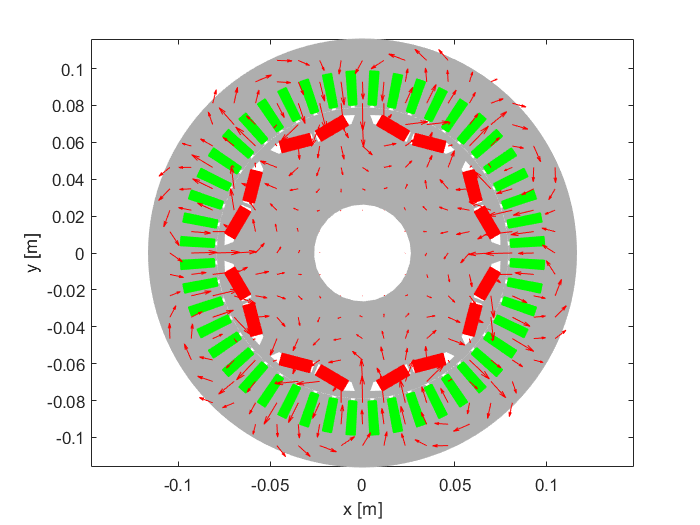


[ux,uy] = pdegrad(p,t,uh);
B = [ux;uy];
t1 = t;
t1(4,:) = t(4,:) + ones(1,nt);
figure
h = plotMesh(p,t,e,material);
set(h, 'LineStyle', 'none');
hold on
pdeplot(p,e,t1,'FlowData',[uy;-ux]);

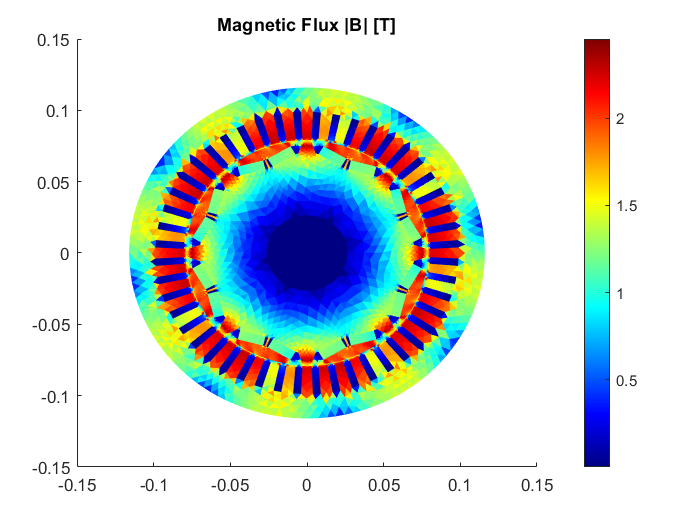


B = [uy;-ux];
Babs = sqrt(B(1,:).^2 +  B(2,:).^2);
figure
pdesurf(p,t,Babs);
colorbar
title('Magnetic Flux |B| [T]')
colormap jet
view([-0.83 90.00])

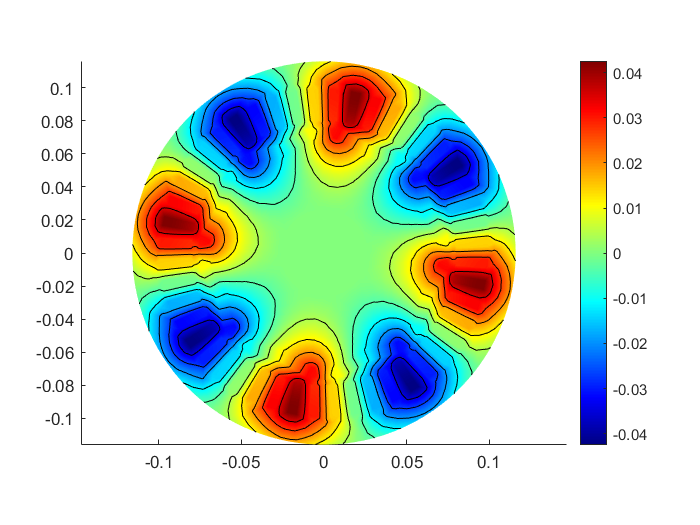


figure
pdeplot(p,e,t,'XYData',uh,Contour="on",ColorMap="jet")

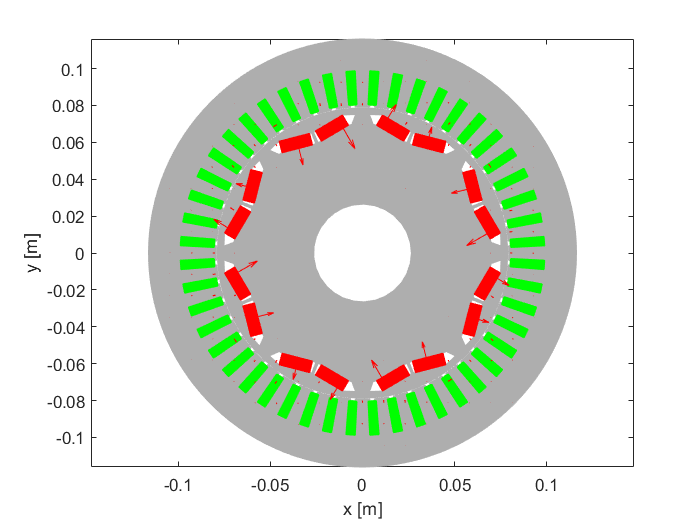

H = grad_f(t(4,:),B,material) - material.nu0*M_vec;
h = plotMesh(p,t,e,material);
set(h, 'LineStyle', 'none');
hold on
pdeplot(p,e,t1,'FlowData',H);

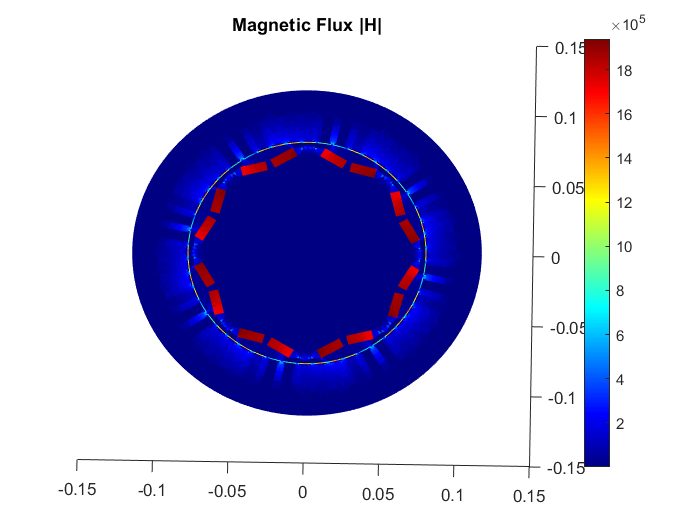



H_abs = sqrt(H(1,:).^2 +  H(2,:).^2);
pdesurf(p,t,H_abs);
colormap jet
colorbar
title('Magnetic Flux |H|')

view([1 90])